# MXB201 Project Description

## Introduction

This document describes the assessment item Model (Theoretical) for MXB201, which for brevity will henceforth be referred to as the "project".  This project forms 30% of your summative assessment for MXB201.  It is to be completed in groups of four.  You are expected to develop working MATLAB implementations of Parts I and II, accompanied by a short technical report targeted at an audience with the same mathematical expertise as you.  You will also record a succinct video presentation in a professional manner, pitching your group's capabilities to a panel of digital health executives.

The due date for submission of this project is the end of Week 13: Friday 2 June, 11:59pm.  Unless extenuating circumstances apply, each group member will receive the same mark for the project.

For the background reading required to complete this project, please refer to the separate Background Reading document and watch the [explanatory video](https://web.microsoftstream.com/video/adbc3546-7506-4349-a6d9-0c6a70af4521).

For details of how your work will be assessed for this project, please refer to the separate Rubric spreadsheet.

## Project Deliverables

- A private GitHub repository containing all the files developed as part of this project.  All files for this project must have been regularly committed to this repository, with meaningful commit messages.  The commit history of your repository forms part of your assessment.  It is expected that each group member's individual contributions will be clearly evident in the commit history.  If this is not the case, it could be considered as evidence of insufficient engagement on the part of an individual, and be grounds for a reduction in that individual's mark compared to the group mark.  **This deliverable accounts for 5% of the project mark and is a requirement for your project to be marked.  Your project ****will not be marked**** if this repository has not been provided.**

- Functioning MATLAB code that implements Parts I and II (see below).  It must comprise two script files: `partI.m` (or `partI.mlx)` and `partII.m` (or `partII.mlx)`.  Executing these scripts must run the full implementations for Parts I and II respectively to completion.  Other scripts and functions forming part of the implementation can be included as necessary.  **This deliverable accounts for 10% of the project mark.**

- A technical report in PDF format of no more than 10 pages.  The report must contain an introduction, separate sections for Parts I and II (details below), conclusions, and references.  You may use whatever software you wish to write the report, provided it is submitted in PDF form.  **This deliverable accounts for 10% of the project mark.**

- A 3-minute recorded video presentation, pitched to a panel of *digital health executives*.  This is a recorded presentation; you do not perform this presentation live to an actual audience.  The hypothetical audience you are targeting in your video will *not *be as mathematically knowledgeable as you.  The purpose of this video is to pitch your group as capable problem-solvers in this field of digital health, competing for a hypothetical contract.  It is *not* the place to go into mathematical detail (the technical report covers that aspect).  You should treat this as an authentic video pitch and approach it with a level of professionalism.  Each group member must speak on video as part of the presentation.  You can be in the same room, or over Zoom, or with separate video sections joined together: it's up to you.  The video [Demo day pitch](https://www.youtube.com/watch?v=7u0cKqRPYhY) provides some good tips for structuring the presentation.  **This deliverable accounts for 5% of the project mark.**

## Private GitHub Repository

One group member should create a private GitHub repository and invite the remaining group members as collaborators.  Also invite your tutor and your unit coordinator as collaborators.  Ensure that these invitations are accepted.

Note that following the project completion, or indeed at any time, other group members can "fork" the repository on GitHub, thereby creating your own private copy (e.g. to show future employers, or just for peace of mind during the project).  But only invite your tutor and unit coordinator to collaborate on exactly one GitHub repository for your group.

## Details on Part I: MRI Diffusion Tensor Imaging

### Input Data

Recall from the Background Reading document that the following data are available following the scan:

- The signal $S_0$ that was recorded for each voxel before any gradient pulses were applied.

- The single $b$-value that was used for all gradient pulses.

- The directions $\mathbf{g}_i$ that were used for each gradient pulse.

- For each gradient direction $\mathbf{g}_i$, the signal $S$ that was recorded for each voxel.

The workspace `dtmri.mat` contains all the data that you will need for Part I, being a single slice from a scan of a single healthy adult brain.

load dtmri
whos

  Name        Size                 Bytes  Class      Attributes

  S         115x90x64            5299200  double               
  S0        115x90                 82800  double               
  b           1x1                      8  double               
  g          64x3                   1536  double               
  mask      115x90                 10350  logical              



As you can see from the workspace, the slice comprises $115 \times 90$ pixels.

Signal values `S` and `S0` should in theory be nonnegative, but the realities of taking measurements using a machine are such that some values will in fact be negative and hence unusable.

For your convenience, a binary `mask` has also been included in the workspace, that demarcates the actual brain tissue within this slice.  Outside this mask, the values of $S$ and $S_0$ will essentially be random noise.

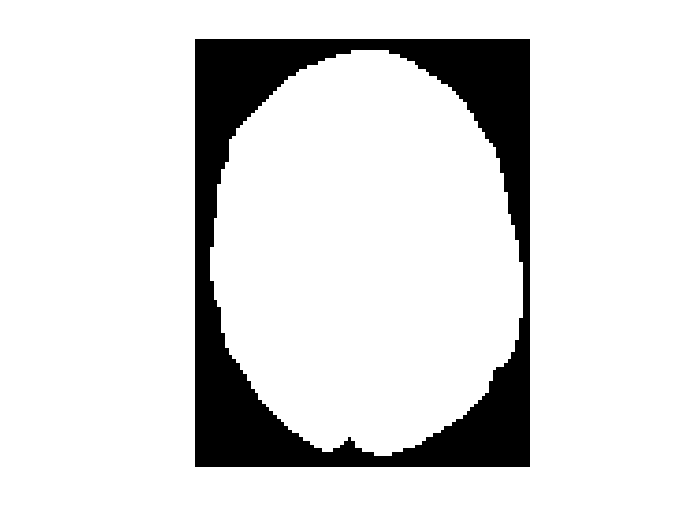

figure, imshow(mask, 'initialmagnification', 'fit')

A total of 64 gradient pulse directions $\mathbf{g}_i$ were used in this scan, as shown.

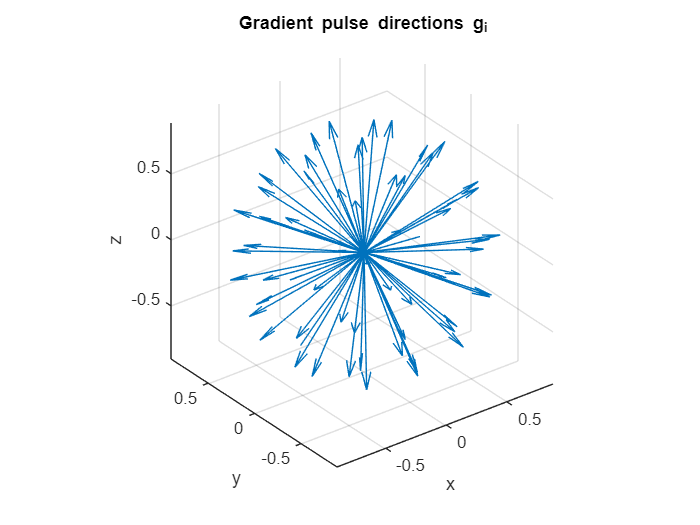

 figure
 quiver3(0*g(:,1), 0*g(:,1), 0*g(:,1), g(:,1), g(:,2), g(:,3))
 axis vis3d
 xlabel x, ylabel y, zlabel z
 title('Gradient pulse directions g_i')

### Your Tasks

- Report: Present the mathematical problem of fitting the diffusion tensor $\mathbf{D}$, which should reference Jiang, et al. [1] and the Background Reading document where appropriate (~1 page).

- Report: Describe what issues arise due to bad or invalid data at any step of the process, and explain how this is handled, with justification (~1/2 -- 1 page).

- Code: Implement your algorithm in MATLAB to calculate the mean diffusivity, fractional anisotropy and principal diffusion direction for each voxel, including handling bad data.

- Code/Report: Produce mean diffusivity map, fractional anisotropy map and principal diffusion direction map resembling those in the Project Description.  Include these figures in your report.

- Video: Present your group's capabilities at producing high quality MRI images, and propose how you would take this further if awarded the contract (~1 minute).

A template MATLAB script `partI_template.m` has been provided.  You are strongly encouraged to use this code as your starting point.

## Details on Part II: Feature Extraction

### Input Data

The directory `faces` contains the 1000 image files you will need for Part II.  They are portable grey map (PGM) files, which can be read into MATLAB using the code provided in the template.

### Your Tasks

- Report: Present the mathematical explanation of eigenfaces, including how to generate the eigenfaces from the data set. (~1 page).

- Report: Present the mathematical explanation of how to build a rudimentary moustache detector by projecting onto $\nu$-dimensional "eigenface space". (~1/2 -- 1 page).

- Code/Report: Implement code in MATLAB to produce the mean face and eigenfaces figures from the Background Reading document.  Include these figures in the report.

- Code: Implement the moustache detector in MATLAB and demonstrate it in operation for a handful of images from the sample set.  Your detector should be able to take a face from the data set as input, and return a yes or no answer as to whether it likely has a moustache.

- Video: Present your group's capabilities at moustache detection, and propose how you would adapt your work to form part of a digital health system that uses MRI data (~ 1 minute).

A template MATLAB script `partII_template.m` has been provided.  You are strongly encouraged to use this code as your starting point.

## **Mode of submission**

The code and technical report are to be uploaded to the submission link on Canvas by the due time and date.  Canvas is the primary source we will use to mark your work.  Your private GitHub repository will be used to grade your collaboration only.

The video presentation can be uploaded to Canvas also.  Or you may upload the presentation as a private or unlisted video to YouTube and provide the link to this recording in your Canvas submission.

The link to your private GitHub repository must also be provided in your submission to Canvas.  You should have invited your tutor and the unit coordinator as collaborators to your repository.

## **Academic Integrity and Referencing**

- This project must be entirely the work of the group members.

- No code (MATLAB or otherwise) sourced from outside this unit may be used in your submission or as the basis of your submission, in whole or in part.

- You must cite any reference material that you take ideas from.

- Your writing must be your own work.  You may not copy directly from any other source, even if it is cited as a reference.

- Direct quotes are exempt from the no-copying rule: you may include direct quotes from other sources provided they are clearly identified as such.

- Mathematical equations are also exempt from the no-copying rule: you may copy equations verbatim, provided you cite the source.

Failure to comply with these requirements will constitute a breach of Academic Integrity, the penalties for which can be severe.  Further information about academic integrity [can be found here](https://www.citewrite.qut.edu.au/academic-integrity/).